clear
root = fileparts(matlab.desktop.editor.getActiveFilename);
root = convertCharsToStrings(root) + "\img\";
dirs = ["regular"; "barrier"; "mask clip"; "valve"; "feather"];
figure
hold on
for i = 1:length(dirs)
    disp(dirs(i));
    path = root+dirs(i);
    files = dir(fullfile(path, '*.jpg'));
    mean_iqm = 0.0;
    for j = 1:length(files)
        path = [files(j).folder '/' files(j).name];
        iqm = image_quality(path);
        plot(i, iqm, 'ok');
        mean_iqm = mean_iqm + iqm / length(files);
    end
    plot([i-0.3, i+0.3], [mean_iqm, mean_iqm], 'k--');
    disp("Mean quality: " + mean_iqm);
end

regular


Quality: 0.022522
Quality: 0.02066
Quality: 0.027405


Mean quality: 0.023529


barrier


Quality: 0.048294
Quality: 0.04274
Quality: 0.050461


Mean quality: 0.047165


mask clip


Quality: 0.041306
Quality: 0.042831
Quality: 0.039642


Mean quality: 0.04126


valve


Quality: 0.04538
Quality: 0.043167
Quality: 0.040405


Mean quality: 0.042984


feather


Quality: 0.041946
Quality: 0.03598
Quality: 0.041641


Mean quality: 0.039856


disp("Reference image");

Reference image


iqm = image_quality(root+"reference.jpg");

Quality: 0.050156


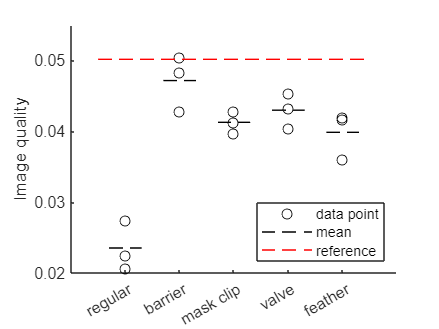

plot([0.5, length(dirs)+0.5], [iqm, iqm], 'r--');
xticks(1:length(dirs));
xticklabels(dirs);
lg = zeros(3, 1);
lg(1) = plot(NaN,NaN,'ok');
lg(2) = plot(NaN,NaN,'k--');
lg(3) = plot(NaN,NaN,'r--');
legend(lg, 'data point','mean','reference', 'Location','southeast');
ylabel("Image quality")

function [iqm] = image_quality(path)

    % load image, resize to 256x256 for consistency
    img = imread(path);
    img = imresize(img, [256, 256]);
    % https://en.wikipedia.org/wiki/YUV#Conversion_to/from_RGB
    i = 0.299*img(:,:,1)+0.587*img(:,:,2)+0.114*img(:,:,3);

    % follow the paper instruction
    af = fftshift(abs(fft2(i))) / sqrt(numel(i));
    m = max(af, [], 'all');
    th = af > (m/1000);
    iqm = sum(th, 'all') / numel(i);

    % visualization
    disp("Quality: " + iqm);
    %figure
    %imshow(i, []);
    %figure
    %image(af);
    %colorbar;
end